split fat cells

cell width too wide split

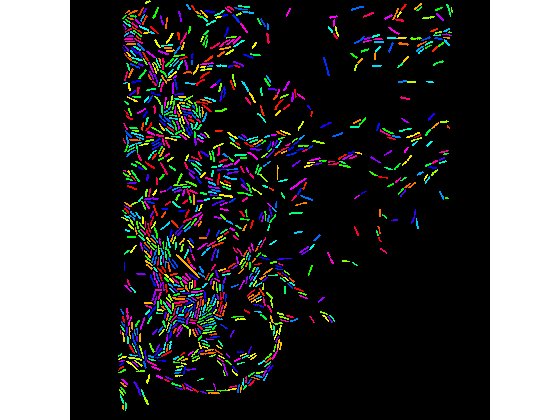

maxCellWidth = 15;
minCellLength = 20;%20-30
H = 1.6;

outcell = false(size(bw4));

% figure,imshow(bw3)
L4 = bwlabel(bw4);
imshowlabel_ys(L4);

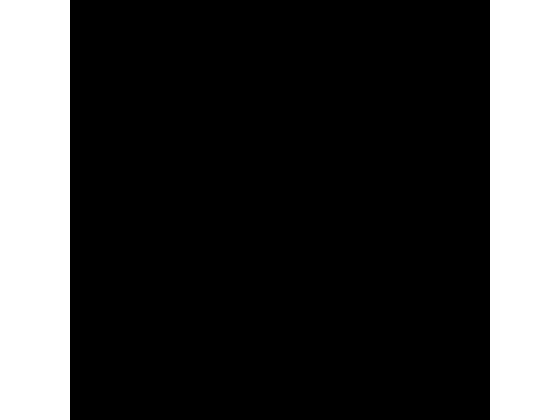

r4 = regionprops(bw4,'MinorAxisLength');
ffat= find(([r4.MinorAxisLength] > maxCellWidth));
goodones = setdiff(1:max(max(L4)), ffat);
goodbw = ismember(L4, goodones);%没有ffat剩下的bw图像
% imshow(goodbw)
fatbw = ismember(L4, ffat);
figure,imshow(fatbw)

rfat = regionprops(fatbw,'MinorAxisLength','PixelIdxList');
% hold on
% for i = 1:numel(rkinky)
%     plot(rkinky(i).ConvexHull(:,1),rkinky(i).ConvexHull(:,2),'r')
% end
% %  figure,
% for i = 1:numel(fkinky)
%     Lcell= +(L3 == fkinky(i)); % + converts logical to double
%     Lcell(Lcell == 1)= fkinky(i);
%     
%     % extract subimages
%     [fx, fy] = find(Lcell);
%     extra= 5;
%     xmin = max(min(fx) - extra, 1);
%     xmax = min(max(fx) + extra, size(Lcell,1));
%     ymin = max(min(fy) - extra, 1);
%     ymax = min(max(fy) + extra, size(Lcell,2));
%     subcell = Lcell(xmin:xmax, ymin:ymax);
%     [cutcell,Ld2] = segCellWatershedTransform(subcell,H);
% %     figure,imshowpair(subcell,cutcell,'montage');
%     
%     
%     s_cutcell = regionprops(cutcell,'MajorAxisLength');
%     while sum([s_cutcell.MajorAxisLength] < minCellLength) && H <= 2
%         %based on celllength judge oversegmentaion
%         H = H + 0.1;
%         [cutcell,Ld2] = segCellWatershedTransform(subcell,H);
%         s_cutcell = regionprops(cutcell,'MajorAxisLength');
%     end
% %         figure,imshowpair(subcell,cutcell,'montage');
%     
%     % ridgeLine = Ld2 == 0;% watershed ridge lines
%     cutline = (Ld2 == 0) & subcell;%cut cell lines
%     % 如果升高H还会有oversegementation， 人工删除细胞分割线
%     while sum([s_cutcell.MajorAxisLength] < minCellLength)
%         [cutcell,cutline] = overSegRecover(cutcell,cutline);
%         s_cutcell = regionprops(cutcell,'MajorAxisLength');
%     end
% %         figure,imshowpair(subcell,cutcell,'montage');
%     
%     % 将cutcell结果复原
%     outcell(xmin:xmax, ymin:ymax) = or(outcell(xmin:xmax, ymin:ymax),cutcell);
% end
% figure,imshow(outcell)
% bw4 = or(goodbw,outcell);
% figure,imshow(bw4)

function [cutcell,Ld2] = segCellWatershedTransform(subcell,H)

subcell = logical(subcell);
D = -bwdist(~subcell);
mask = imextendedmin(D,H);
D2 = imimposemin(D,mask);
Ld2 = watershed(D2);
cutcell = subcell;
cutcell(Ld2 == 0) = 0;

end

function [cutcell,cutline] = overSegRecover(cutcell,cutline)
% 找出被分割的最小的区域 每次添加一次分割线进行overlap复原
L_cutcell = bwlabel(cutcell);

s_cutcell = regionprops(cutcell,'MajorAxisLength','PixelIdxList');
fminRegionIdx = find([s_cutcell.MajorAxisLength] == min([s_cutcell.MajorAxisLength]));
s_cutline = regionprops(cutline,'PixelIdxList');

oversegRegion = L_cutcell == fminRegionIdx;

for i = 1:numel(s_cutline)
    overlapRegion = oversegRegion;
    overlapRegion(s_cutline(i).PixelIdxList) = 1;
    s_OLRegion = regionprops(overlapRegion,'PixelIdxList');
    
    if numel(s_OLRegion) == 1
        cutline(s_cutline(i).PixelIdxList) = 0;
        cutcell = cutcell|overlapRegion;
        return
    end
    
end
end

